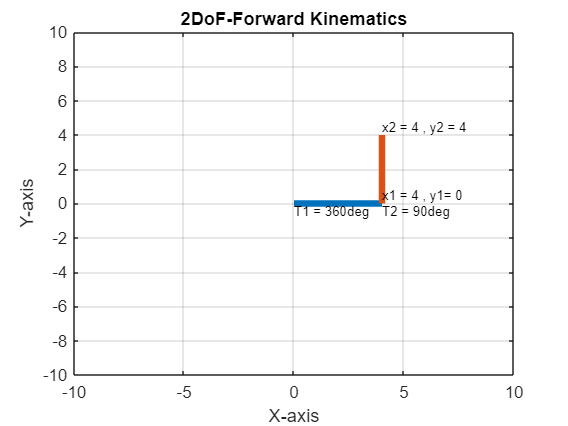

% Forward Kinematics of 2DOF robotics arm %
close all
clear all
clc

%% input values %%
l1 = 4;   % length of link-1 = l1;
l2 = 4;   % length of link-2 = l2;
theta1 = linspace(0,360,4);  % angle at joint-1
theta2 = linspace(0,90,4);  % angle at joint-2

%% for loop iteration %%
count = 1; % counter
for i = 1:length(theta1)
    THETA1 = theta1(i);
    for j = 1:length(theta2)
        THETA2 = theta2(j);
        
        % coordinates of world frame %
        x0 = 0;
        y0 = 0;
        % another end of link-1 %
        x1 = l1*cosd(THETA1);
        y1 = l1*sind(THETA1);
        % end-effector %
        x2 = x1 + l2*cosd(THETA1+THETA2);
        y2 = y1 + l2*sind(THETA1+THETA2);
        
        txt1 = ['T1 = ', num2str(THETA1), 'deg'];
        txt2 = ['T2 = ', num2str(THETA2), 'deg'];
        txtmid = ['x1 = ' , num2str(x1),' , ','y1= ', num2str(y1)];
        txtend = ['x2 = ', num2str(x2),' , ','y2 = ', num2str(y2)];
        
        %plotting
        plot([x0 x1],[y0 y1],[x1 x2],[y1 y2],'LineWidth',4);
        grid on
        xlabel('X-axis')
        ylabel('Y-axis')
        title('2DoF-Forward Kinematics')
        text(x0,y0,txt1,'FontSize',8,'VerticalAlignment','top')
        text(x1,y1,txt2,'FontSize',8,'VerticalAlignment','top')
        text(x1,y1,txtmid,'FontSize',8,'HorizontalAlignment','left','VerticalAlignment','bottom')
        text(x2,y2,txtend,'FontSize',8,'HorizontalAlignment','left','VerticalAlignment','bottom')
        axis([-10 10 -10 10])
        pause(3);
        count = count + 1;
    end
end